fid=fopen('Comp_Nodes_S11.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';



ind2 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     48    48    48    49    49    49    50    50    50    50    50    50    50    50    50    50    50    50    51    51
    66    67    68    67    66    65    64    64    64    64    64    66    66    66    67    68    68    68    67    67
   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197
    68    68    68    70    69    69    71    70    71    73    72    72    72    73    72    72    72    73    74    74


sum(ind2)

ans =    379   380   381   383   381   380   382   381   382   384   383   385   385   386   386   387   387   388   389   389


mean(sum(ind2))

ans = 383.9000

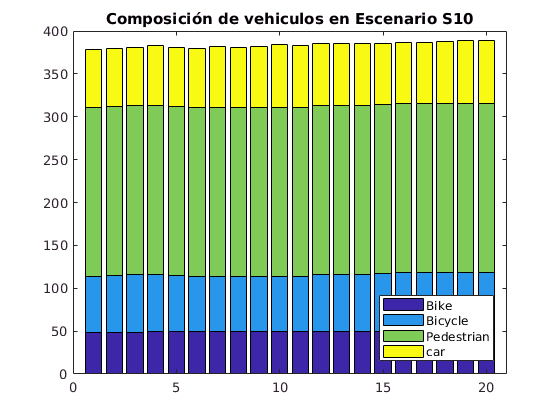

%Target Tomás

% #Cars   = 96
% #Ped    = 176
% #Ciclos = 112
% #Total Veh = 208
% #Total = 384

figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthEast');
xlim([0 21])

Escenario baja densidad


fid=fopen('Comp_Nodes_S11_L.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';



ind2 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    36    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
    45    44    43    43    44    43    43    43    43    43    41    42    42    42    43    42    42    43    43    43


sum(ind2)

ans =    210   210   209   209   210   209   211   212   213   212   210   212   212   212   214   214   215   217   218   218


mean(sum(ind2))

ans = 212.3500

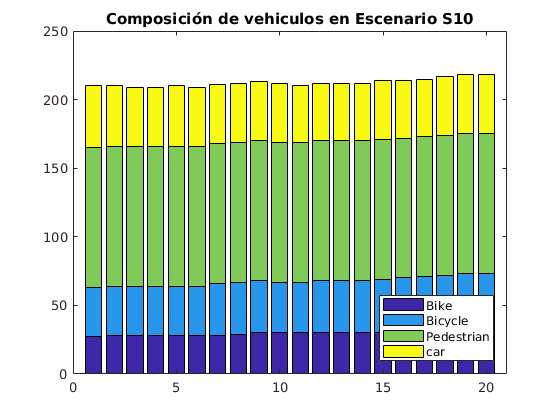

%Target Tomás

% #Cars   = 53
% #Ped    = 98
% #Ciclos = 62
% #Total Veh = 115
% #Total Nodes = 213

figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthEast');
xlim([0 21])